# QN1: Reservoir release for hydropower 

QN. A hydropower dam on a river receives known monthly inflows I_t (Mm^3). The reservoir holds between 20 and 100 Mm^3 and starts the year at 50 Mm^3. Monthly release must be between 10 and 40 Mm^3. Energy earned per Mm^3 released depends on the month's tariff k_t (GWh-equivalent per Mm^3). Determine the monthly releases R_t that maximize total energy for the year, while ending the year with at least as much water as it started with.

MATHEMATICAL MODEL (t = 1..12) Maximize Z = sum_t k_t * R_t Subject to S_t = S_0 + sum_{j<=t} (I_j - R_j) (water balance) S_min <= S_t <= S_max (storage limits) S_12 >= S_0 (sustainability) R_min <= R_t <= R_max (release limits) Solver: linprog (Optimization Toolbox). linprog minimizes, so f = -k.

clear; clc; close all;
if ~license('test','Optimization_Toolbox'), error('Optimization Toolbox is not installed/licensed.'); end

months = {'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'};
I  = [20 18 25 35 40 30 22 20 24 32 38 28]';           % inflow (Mm^3)
k  = [0.9 0.9 0.9 1.0 1.0 1.0 1.1 1.1 1.1 1.2 1.2 1.2]'; % tariff weight
S0 = 50; Smin = 20; Smax = 100; Rmin = 10; Rmax = 40;
n  = 12;
L  = tril(ones(n));                 % cumulative-sum matrix

f  = -k;                            % maximize -> minimize negative
A  = [  L;                          % S_t >= Smin
       -L;                          % S_t <= Smax
        ones(1,n) ];                % S_12 >= S0
b  = [ S0 + L*I - Smin;
       Smax - S0 - L*I;
       sum(I) ];
lb = Rmin*ones(n,1);
ub = Rmax*ones(n,1);

opts = optimoptions('linprog','Display','none');
[R, fval, exitflag] = linprog(f, A, b, [], [], lb, ub, opts);
if exitflag ~= 1, error('No optimal solution found (exitflag = %d)', exitflag); end

S = S0 + cumsum(I - R);
fprintf('Maximum energy Z = %.2f units\n\n', -fval);

Maximum energy Z = 362.40 units



fprintf('%-5s %8s %9s %9s\n','Month','Inflow','Release','Storage');

Month   Inflow   Release   Storage


for t = 1:n
    fprintf('%-5s %8.1f %9.1f %9.1f\n', months{t}, I(t), R(t), S(t));
end

Jan       20.0      10.0      60.0
Feb       18.0      10.0      68.0
Mar       25.0      10.0      83.0
Apr       35.0      40.0      78.0
May       40.0      18.0     100.0
Jun       30.0      30.0     100.0
Jul       22.0      40.0      82.0
Aug       20.0      14.0      88.0
Sep       24.0      40.0      72.0
Oct       32.0      40.0      64.0
Nov       38.0      40.0      62.0
Dec       28.0      40.0      50.0


## PLOTS

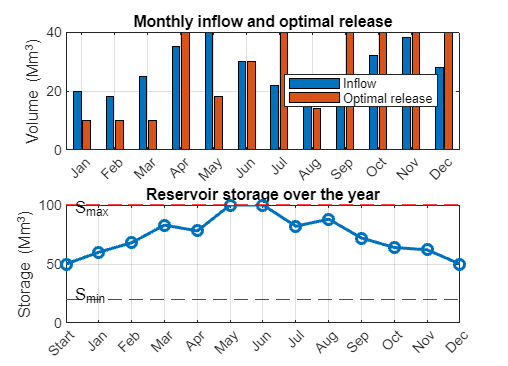

figure('Position',[100 100 900 650]);
subplot(2,1,1);
bar(1:n, [I R]); grid on;
set(gca,'XTick',1:n,'XTickLabel',months);
ylabel('Volume (Mm^3)'); legend('Inflow','Optimal release','Location','best');
title('Monthly inflow and optimal release');

subplot(2,1,2);
plot(0:n, [S0; S], '-o','LineWidth',1.8); hold on;
plot([0 n],[Smax Smax],'r--'); plot([0 n],[Smin Smin],'r--');
text(0.2,Smax-3,'S_{max}'); text(0.2,Smin+3,'S_{min}');
grid on; set(gca,'XTick',0:n,'XTickLabel',['Start' months]);
ylabel('Storage (Mm^3)'); title('Reservoir storage over the year');
saveas(gcf,'QN1_plots.png');